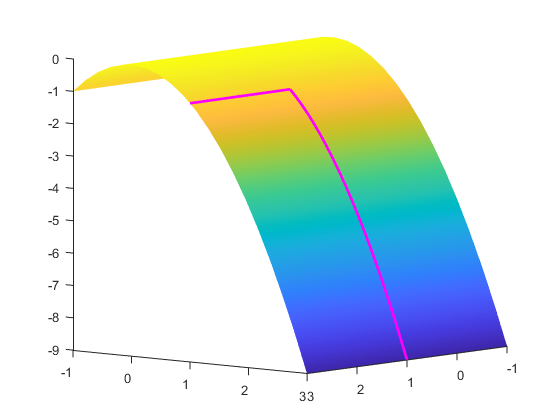

%First graph:
x1 = linspace(-1, 3, 20);
x2 = linspace(-1, 3, 20);
[X1, X2] = meshgrid(x1, x2);
Z = -X2.^2;

figure
hold on
surf(X1, X2, Z);
view([-229.5000, 7.2000]);
shading interp

x1_line = ones(1, 20);
x2_line = linspace(1, 3, 20);

%Approach from x1
z_line = -x1_line.^2;
plot3(x2_line, x1_line, z_line, 'm', 'LineWidth', 2);

%Approach from x2
z_line = -x2_line.^2;
plot3(x1_line, x2_line, z_line, 'm', 'LineWidth', 2);


%Second graph:
x1 = linspace(-1, 1, 20);
x2 = linspace(-1, 1, 20);
[X1, X2] = meshgrid(x1, x2);
Z2 = -X1.^2-X2.^2;
figure
hold on
grid on
shading interp
surf(X1, X2, Z2);
view([-229.5000, 7.2000]);
xlabel('x1')
ylabel('x2')
zlabel('z')

%points = transpose([X1(:) X2(:)]);

syms x1 x2
j = jacobian([-x1^2-x2^2], [x1, x2])

$$j = \left(\begin{array}{cc} -2\,x_{1} & -2\,x_{2} \end{array}\right)$$

approx_at = [0 0]

approx_at =      0     0


eval_at = -approx_at(1)^2-approx_at(2)^2

eval_at = 0

slope_at = subs(j, [x1 x2], approx_at)

$$slope\_at = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

test = X1-approx_at(1)

test =    -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000
   -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000
   -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000
   -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000
   -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.894

test2 = X2-approx_at(2)

test2 =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947   -0.8947
   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895   -0.7895
   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842   -0.6842
   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.5789   -0.57

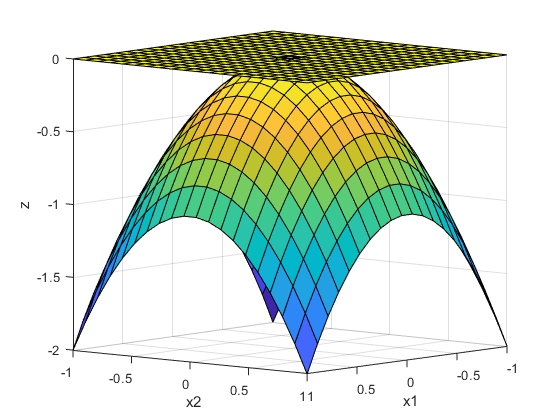

Z3 = (slope_at(1)*test)+(slope_at(2)*test2)+eval_at;
surf(X1, X2, double(Z3));